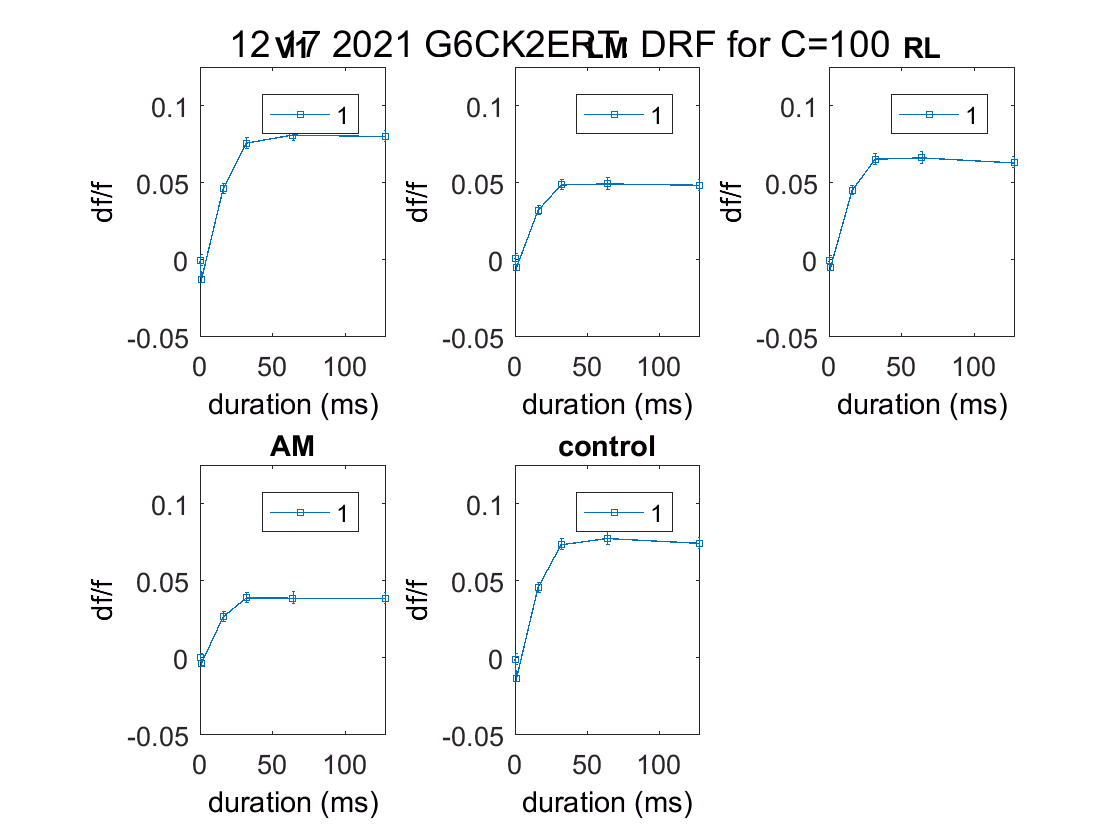

% DRF for ONE CONTRAST - LOG
% all VIS AREAS

figure 
clear titleText
titleText = sprintf(': DRF for C=100%'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

yMax = 0.125;

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr
    
    for c = 1:length(uniqueContrasts)

    clear d
    for d = 1:length(uniqueDurations) % at each duration
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,cthDthTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(d) = dthCRF(d)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value foreach contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthDthTrials)); % sum trials, not length
            durStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end d loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        x_axis = [1:length(uniqueDurations)];
        x_axis = [(uniqueDurations)];
        errorbar(x_axis,dthCRF,durStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.05 yMax]) 
        xlim([min(x_axis), max(x_axis)])
        ylabel('df/f')
        xlabel('duration (ms)')

%         clear xt
%         xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%         set(gca,'xtick',1:7); 
%         set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end c loop

hold on
legend(cons4Legend)
    
end % end i loop

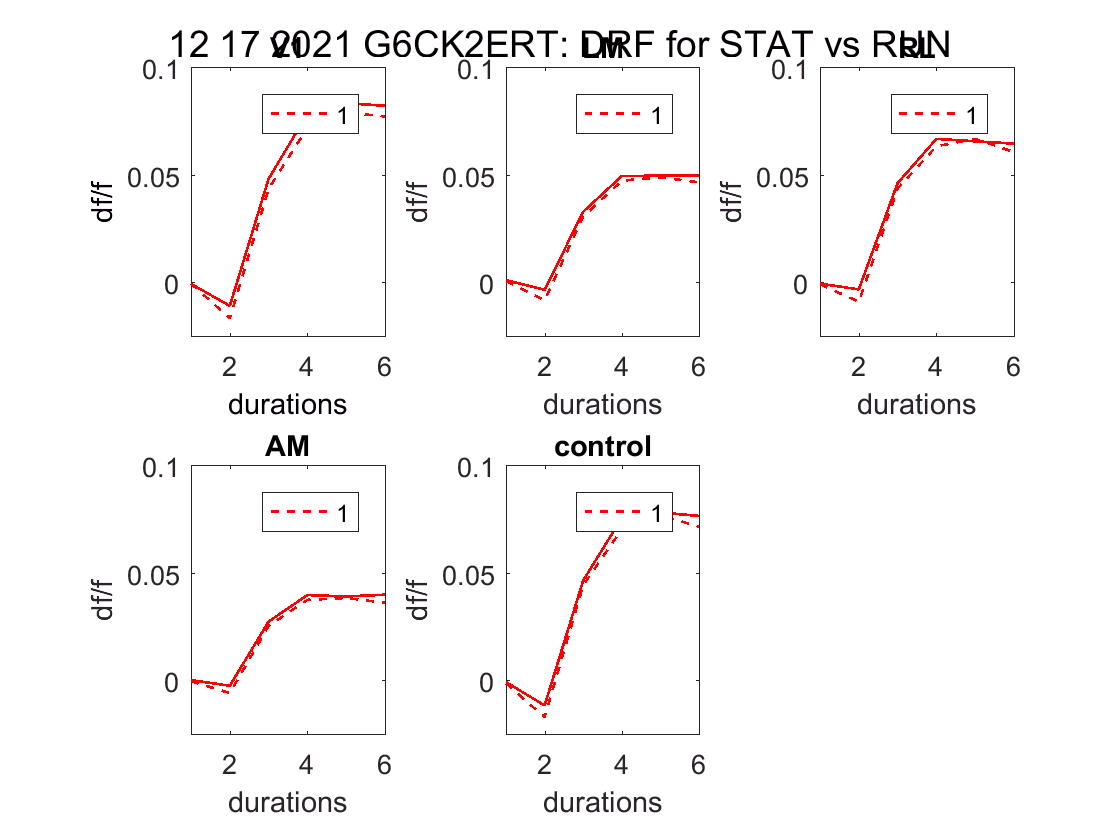

% STAT & RUN SAME PLOT

%durat = 6;
durat = 1:length(uniqueDurations);

yMax = 0.1;

figure 
clear titleText
titleText = sprintf(': DRF for STAT vs RUN'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

lineColors1 =  {'--k','--m','--c','--g','--b','--r'};
lineColors2 =  {'k','m','c','g','b','r'};
lineWides = [1,1];

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear c
    for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
    clear d
    %for d = 1:length(uniqueDurations) % at each duration
    for d = durat
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthLOWtrials
             idxCthDthLOWtrials = intersect(idxCthDthTrial,idxLowRunTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthLOWtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthLOWtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(d) = dthCRF(d)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthLOWtrials)); % length
            contStdErr(1,d) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        %x_axis = uniqueDurations;
        x_axis = [1:length(uniqueDurations)];
        %errorbar(x_axis,dthCRF,contStdErr,'-g','MarkerSize',3) 
        %errorbar(x_axis,dthCRF,contStdErr,lineColors(d),'MarkerSize',lineWides(1)) 
        plot(x_axis,dthCRF,lineColors1{d},'linewidth',lineWides(1))
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('duration')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        
        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same butRUN

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear c
    for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
        clear d
        for d = 1:length(uniqueDurations) % at each duration
        %for d = durat
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthHitrials
             idxCthDthHiTrials = intersect(idxCthDthTrial,idxHiRunTrials); % idxLowRunTrials was made in runSpeed2 script
             
             % clear idxCthDthLOWtrials
             % idxCthDthLOWtrials = idxLowRunTrials(intersect(idxCthDthTrial,idxLowRunTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthHiTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthHiTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(d) = dthCRF(d)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthHiTrials)); % length
            contStdErr(1,d) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
         %x_axis = uniqueDurations;
        %x_axis = [1:length(uniqueDurations)];
        %errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3)
        %errorbar(x_axis,dthCRF,contStdErr,lineColors(d),'MarkerSize',lineWides(2)) 
        plot(x_axis,dthCRF,lineColors2{d},'linewidth',lineWides(2))
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('durations')

%         clear xt
%         xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%         set(gca,'xtick',1:7); 
%         set(gca,'xticklabel',xt);
        
        hold on  
        
    end % end d loop
    
    legend(cons4Legend)

hold on
    
end % end i loop



% for non log

%         x_axis = uniqueContrasts;
%         errorbar(x_axis,dthCRF,contStdErr,'-g','MarkerSize',3) % -s seemed to get diff color for each dur?
%         title(reigons{i})
%         
%         ylim([-0.01 yMax]) 
%         xlim([min(x_axis), max(x_axis)])
% 
%         ylabel('df/f')
%         xlabel('contrast (%)')
